# Sea Surface Temperature Explorer

## Sea Surface Temperature

temperatureFiles = listdatafiles;  % Get list of available data files
file = temperatureFiles(3);
load(file)

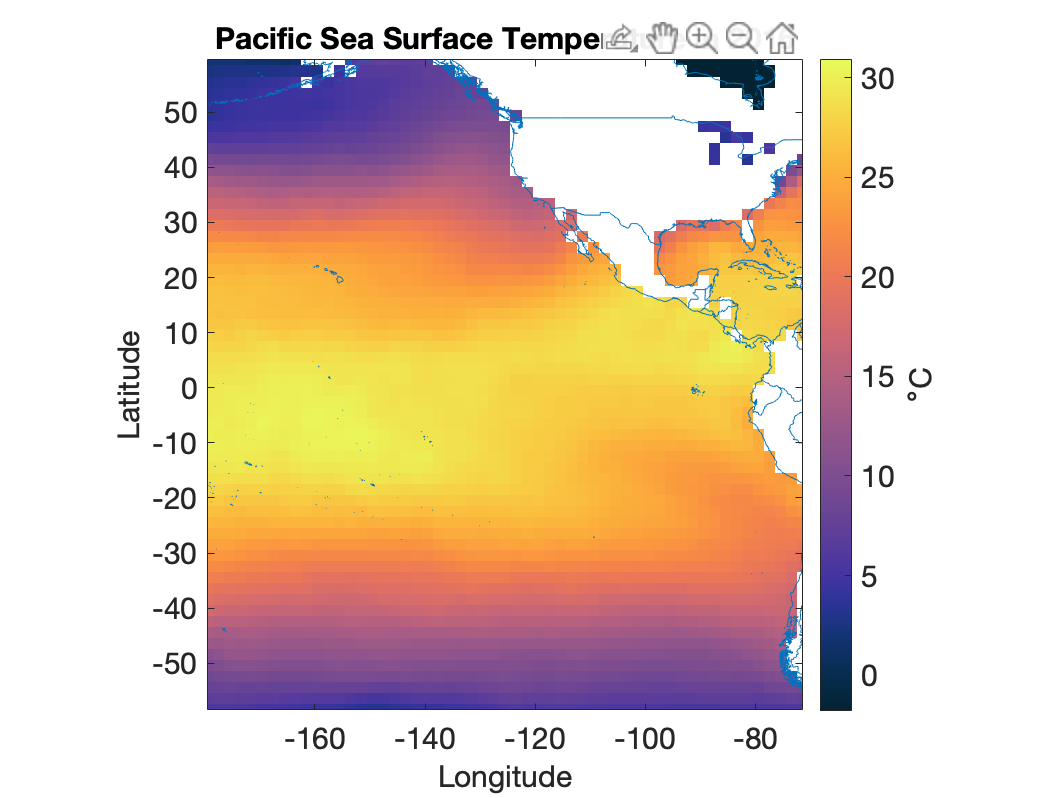

[firstyear,lastyear] = bounds(year(t)); % Year limits

[tmin,tmax] = bounds(sst,"all");
climits = [tmin, tmax];                 % Color limits

Year = 1982;
animate = true;

if ~animate
    sstmap(lat,lon,sst,t,Year,climits);
    sstmaptitle(file,Year)

else
    clf
    for Year = firstyear:lastyear
        sstmap(lat,lon,sst,t,Year,climits);
        sstmaptitle(file,Year)

        pause(.01)
    end
end

## Temperature Trends

View the annual trends in temperature changes over the entire history of the dataset. Black dots indicate values where the change is statistically significant, as determined by a simple Mann-Kendall test.

ssttrend = trend(sst);        % Annual trend
sig = mann_kendall(sst);     % Statistical significance

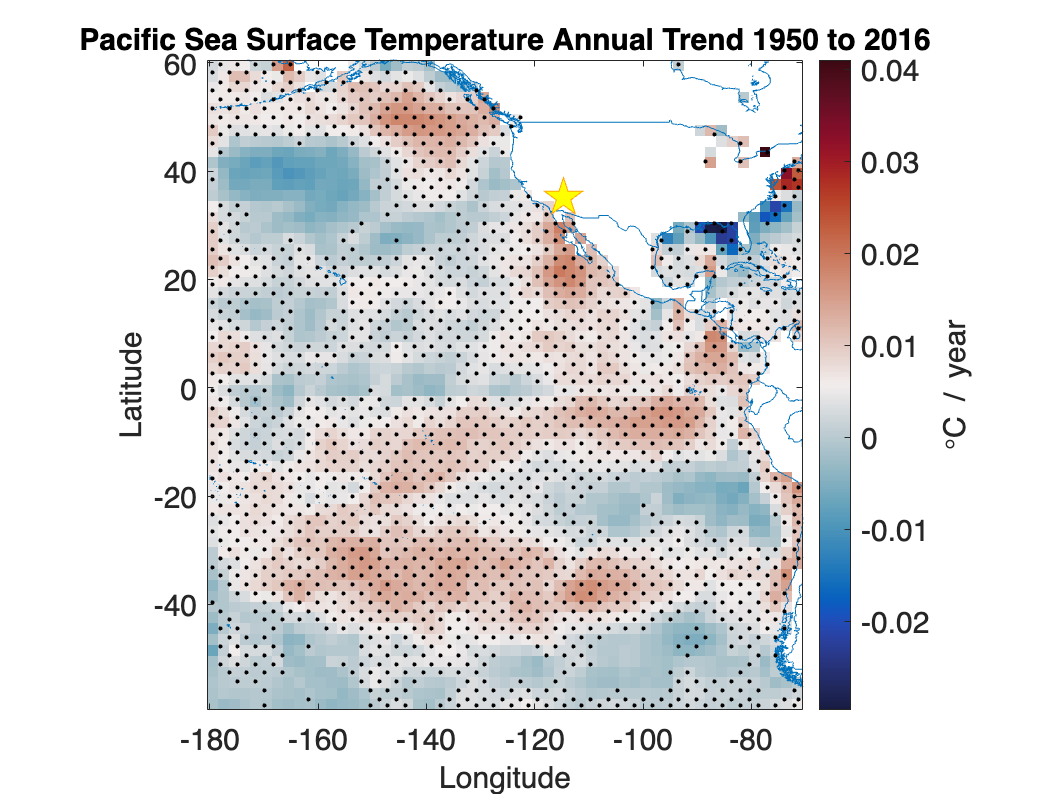

trendmap(lon,lat,ssttrend,file,t);
% Mark Latitude and Longitude for time history plot
Latitude = mean(lat);
Longitude = mean(lon);
marklatlon(Latitude,Longitude);

% Stipple
showstipple = true;
if showstipple
    hold on 
    stipple(lon,lat,sig)
    hold off
end

% Colormap
cmap = "balance";
center = false;
trendmapcolor(cmap,center)

## Temperature History

Select a location in the plot above.

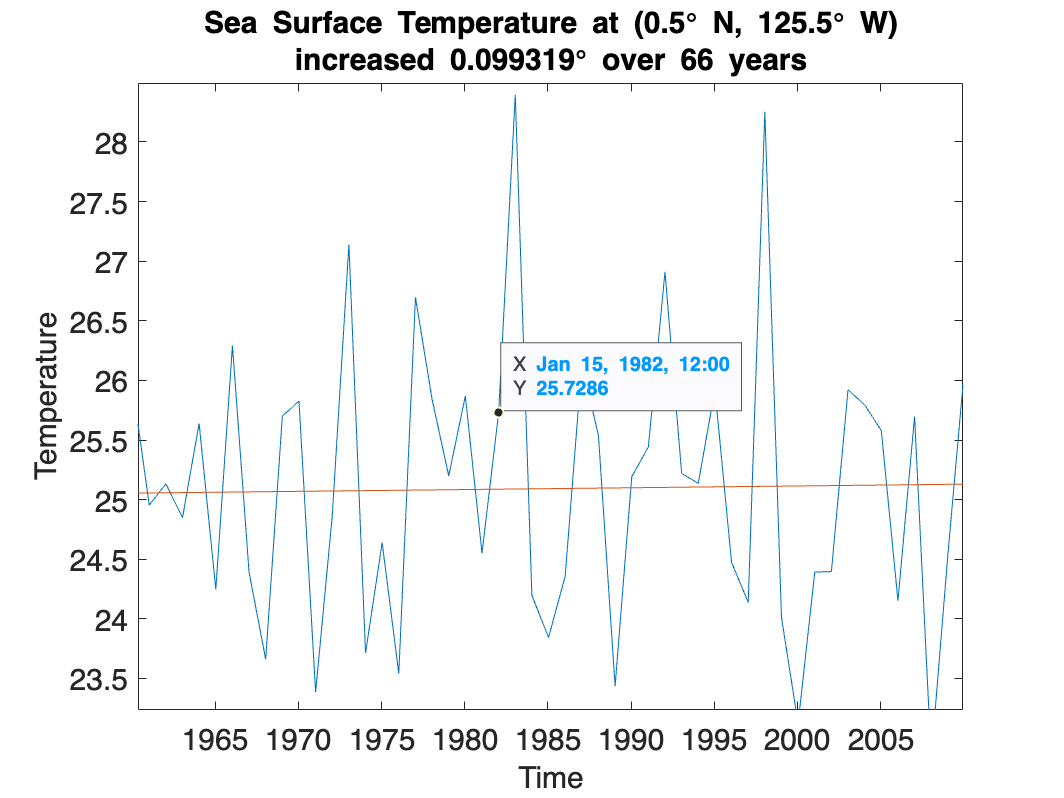

 

% Plot timeseries of temperature at selected location
sstplot(lat,lon,sst,t,Latitude,Longitude)

## Acknowledgements

This application uses the [Climate Data Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/70338-climate-data-toolbox-for-matlab), authored by Chad A. Greene et. al. The application is based on Chad's tutorial, [*The Climate Data Toolbox for MATLAB - Analyzing Trends & Global Warming*](https://www.youtube.com/watch?v=t46dTVp7NHY)*. *The data files Pacific.mat and NorthAtlantic.mat are modified versions of the files pacific_sst.mat and north_atlantic_sst.mat provided in the toolbox. The data were decimated from monthly to annual, and regularized to common data types (doubles for numeric, datetime for dates). Data file Global.mat was downloaded from NOAA, transformed to match format of the others.

Chad A. Greene, Kaustubh Thirumalai, Kelly A. Kearney, Jose Miguel Delgado, Wolfgang Schwanghart, Natalie S. Wolfenbarger, Kristen M. Thyng, David E. Gwyther, Alex S. Gardner, and Donald D. Blankenship. The Climate Data Toolbox for MATLAB. *Geochemistry, Geophysics, Geosystems* 2019. [doi:10.1029/2019GC008392](https://doi.org/10.1029/2019GC008392)